

col_vals = [];
row_vals = [];
h5_mat =zeros(5,5);
size(h5_mat,1)

ans = 5

cc= 0;
for i=4: size(h5_mat,1) + 3
    for j=4:size(h5_mat,2)+3
        cc=cc+1;
        fprintf('progress: %d / %d \n', cc, size(h5_mat,1)*size(h5_mat,2));
        n_cols = ceil(10^(0.5*i));
        n_rows = ceil(10^(0.5*j));
        row_vals = [row_vals, n_rows];
    
        s = calculate_file_sizes_(n_rows, n_cols);
        csv_size = s{1,"size_mb"};
        h5_size = s{2,"size_mb"};
        h5_mat(j-3,i-3) = csv_size/h5_size;
    end
    col_vals = [col_vals, n_cols];
end

progress: 1 / 25 
progress: 2 / 25 
progress: 3 / 25 
progress: 4 / 25 
progress: 5 / 25 
progress: 6 / 25 
progress: 7 / 25 
progress: 8 / 25 
progress: 9 / 25 
progress: 10 / 25 
progress: 11 / 25 
progress: 12 / 25 
progress: 13 / 25 
progress: 14 / 25 
progress: 15 / 25 
progress: 16 / 25 
progress: 17 / 25 
progress: 18 / 25 
progress: 19 / 25 
progress: 20 / 25 
progress: 21 / 25 
progress: 22 / 25 
progress: 23 / 25 
progress: 24 / 25 
progress: 25 / 25 


h5_mat

h5_mat =     1.5004    1.5198    1.5316    1.5333    1.5319
    1.8717    1.8806    1.8862    1.8869    1.8862
    2.0296    2.0329    2.0351    2.0353    2.0350
    2.0856    2.0867    2.0873    2.0874    2.0874
    2.1040    2.1043    2.1045    2.1045    2.1045


row_vals = unique(row_vals);

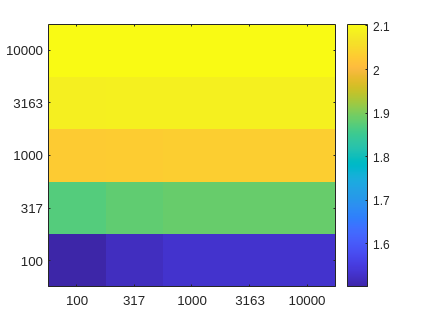

image(flip(h5_mat),"CDataMapping","scaled")
colorbar

xticks([1:size(h5_mat,1)])
xticklabels(col_vals)


yticks([1:size(h5_mat,2)])
yticklabels(flip(row_vals))

function [size_table] = calculate_file_sizes_(n_rows, n_cols)
table = generate_data(n_rows, n_cols);

%.csv
writetable(table,"test_data/dat.csv")
%.Parquet
parquetwrite("test_data/dat.parquet", table)

%.h5
h5filename = "test_data/dat.h5";
if exist(h5filename)
    delete(h5filename)
end
col_names = table.Properties.VariableNames;
for i=1: length(col_names)
    c_name = col_names(i);
    h5_dir = string(strcat('/',c_name));
    data_to_write = table{:,i};
    h5create(h5filename, h5_dir, size(data_to_write),"Datatype",class(data_to_write))
h5write(h5filename, h5_dir, data_to_write)
end

i=struct2table(dir("test_data/dat*"));
i.size_mb = i.bytes /(1024^2);
size_table=i(:, ["name", "size_mb"]);
end


function [data_table]=generate_data(n_rows, n_cols)
data = rand( n_rows, n_cols)*100;
data_table= array2table(data);
end